clear;clc;


## Hydrodynamic Coefficient from WAMIT

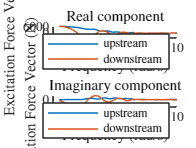

D_space = 4;
%filename=fprintf('hydro/2WEC_Spacing_4p00m.h5',D_space);
filename='hydro/2WEC_Spacing_4p00m.h5';
hydro = convh5_v2(filename);

C_f1 = hydro.float_up.dry_mass+squeeze(hydro.float_up.Add_mass(3,3,:))';
L_hs_f1 = 1./hydro.float_up.K(3,3);
R_rad_f1 = 1./squeeze(hydro.float_up.Rad_damping(3,3,:))';
Fex_f1 = squeeze(complex(hydro.float_up.Fex_re,hydro.float_up.Fex_im));

C_f2 = hydro.float_dn.dry_mass+squeeze(hydro.float_dn.Add_mass(3,15,:))';
L_hs_f2 = 1./hydro.float_dn.K(3,3);
R_rad_f2 = 1./squeeze(hydro.float_dn.Rad_damping(3,15,:))';
Fex_f2 = squeeze(complex(hydro.float_dn.Fex_re,hydro.float_dn.Fex_im));

phase_shift_WECs = (angle(Fex_f1) - angle(Fex_f2))

plot(hydro.w,phase_shift_WECs/2/pi*360)

%% Fex Validation
figure (1)
subplot(2,1,1)
hold on
plot(hydro.w,real(Fex_f1(3,:)))
plot(hydro.w,real(Fex_f2(3,:)))
hold off
xlabel("Frequency (rad/s)")
ylabel("Excitation Force Vector (N)")
legend("upstream","downstream")
title("Real component")
subplot(2,1,2)
hold on
plot(hydro.w,imag(Fex_f1(3,:)))
plot(hydro.w,imag(Fex_f2(3,:)))
hold off
xlabel("Frequency (rad/s)")
ylabel("Excitation Force Vector (N)")
legend("upstream","downstream")
title("Imaginary component")

## PMSM Parameter

%%Machine parameters
lambda = 0.483; %From datasheet with series connection
pp=12;
rx=75;
J=1.786e-2;
B=1/350;
Rs=5.87;
Lq=(53.60e-3/1.5);
r= 0.0636651;
radstorpm=60/(2*pi);

## Underwater Cable Parameter

A. Beddard and M. Barnes, "HVDC cable modelling for VSC-HVDC applications," *2014 IEEE PES General Meeting | Conference & Exposition*, National Harbor, MD, USA, 2014, pp. 1-5, doi: 10.1109/PESGM.2014.6939059.

*Copper resistivity is typically given as $$1.68\times10^{-8} \, \Omega/m $$. It has been increased to $$2.2\times10^{-8} \, \Omega/m $$  for the cable model due to stranded nature of the cable.

The skin depth $\(\delta\)$ quantifies the extent of the skin effect. Defined as the distance from the surface where the current density decreases to $\(e^{-1}\) (\(\approx 37\%\))$ of its surface value, it is calculated as:


$$$
\delta = \sqrt{\frac{2}{\gamma \omega \mu}},
$$$


where $\(\mu\)$ is the material permeability, $\(\omega\)$ is the angular frequency, and $\(\gamma\)$ is the electrical conductivity. The current density $\(J(r)\)$ at a depth $\(r\)$ within the conductor follows an exponential decay:


$$$

J(r) = J_0 e^{-r / \delta},
$$$


where $\(J_0\)$ is the current density at the conductor surface.

For conductors with a radius $\(R_\mathrm{c}\)$ exceeding $\(\delta\)$, integrating $\(J(r)\)$ reveals that approximately $$ 86\ \%$$ of the total current flows within the skin depth, while $$14\ \%$$ is distributed deeper inside the conductor. However, for typical power transmission lines using copper at 60 Hz, $\(\delta \approx 8.5 \, \mathrm{mm}\)$, which exceeds the radius of most conductors in practical use. Thus, the assumption $\(R_\mathrm{c} < \delta\)$ holds, and the current density can be approximated as uniform across the cross-section.

gam = 1/2.2e-8; % (Simens/m) stranded copper wire conductivity per length
mu = 1.256629e-6; %Absolute permeability H/m
Tp = 8; % 8 seconds of dominant period of wave input
omega = 2*pi/Tp; 
d_skin = sqrt(2/gam/omega/mu);

D_2_grid = 20000; % 20 km
R_cable = 1/gam*D_2_grid;
